clear; close all; rosshutdown

Shutting down global node /matlab_global_node_16893 with NodeURI http://192.168.1.5:14623/


ipaddress = "http://192.168.1.11:11311";
rosinit(ipaddress);

Initializing global node /matlab_global_node_38193 with NodeURI http://192.168.1.5:12146/


rostopic list

/clock                        
/gazebo/link_states           
/gazebo/model_states          
/gazebo/parameter_descriptions
/gazebo/parameter_updates     
/gazebo/performance_metrics   
/gazebo/set_link_state        
/gazebo/set_model_state       
/rosout                       
/rosout_agg                   
/tb3_0/cmd_vel                
/tb3_0/imu                    
/tb3_0/joint_states           
/tb3_0/odom                   
/tb3_0/scan                   
/tb3_1/cmd_vel                
/tb3_1/imu                    
/tb3_1/joint_states           
/tb3_1/odom                   
/tb3_1/scan                   
/tb3_2/cmd_vel                
/tb3_2/imu                    
/tb3_2/joint_states           
/tb3_2/odom                   
/tb3_2/scan                   
/tf                           
/tf_static                    


**Move the Robot**

Create a publisher for the `/cmd_vel` topic  and the corresponding message containing the velocity values. Use the  publisher with structure format messages for better performance.

velocity = 0.1;     % meters per second
robotCmd = rospublisher("/tb3_0/cmd_vel","DataFormat","struct");
velMsg = rosmessage(robotCmd);

Set the forward velocity (along the *X*-axis) of the robot based on the `velocity` variable and publish the command to the robot. Let it move for a moment, and then bring it to a stop.

velMsg.Linear.X = velocity;
send(robotCmd,velMsg)
pause(10)
velMsg.Linear.X = 0;
send(robotCmd,velMsg)

To view the type of the message published by the velocity topic, execute the following:

rostopic type /tb3_0/cmd_vel

geometry_msgs/Twist


The topic expects messages of type `geometry_msgs/Twist`, which is exactly the type of the `velMsg` created above.

To view which nodes are publishing and subscribing to a given topic, use the command: [`rostopic`](https://it.mathworks.com/help/ros/ref/rostopic.html)` info TOPICNAME`. The following command lists the publishers and subscribers for the velocity topic. MATLAB is listed as one of the publishers.

rostopic info /tb3_0/cmd_vel

Type: geometry_msgs/Twist
 
Publishers:
* /matlab_global_node_38193 (http://192.168.1.5:12146/)
 
Subscribers:
* /gazebo (http://192.168.1.11:34303/)


**Receive Robot Position and Orientation**

The TurtleBot uses the `/odom` topic to publish its current position and orientation (collectively  denoted as pose). Since the TurtleBot is not equipped with a GPS system, the pose will be relative to the pose that the robot had when it was  first turned on. 

Create a subscriber for the odometry messages

odomSub = rossubscriber("/tb3_0/odom","DataFormat","struct");
rostopic info /tb3_0/odom

Type: nav_msgs/Odometry
 
Publishers:
* /gazebo (http://192.168.1.11:34303/)
 
Subscribers:
* /matlab_global_node_38193 (http://192.168.1.5:12146/)


Wait for the subscriber to return data, then extract the data and assign it to variables `x`, `y`, and `z`:

odomMsg = receive(odomSub,3);
pose = odomMsg.Pose.Pose;
x = pose.Position.X;
y = pose.Position.Y;
z = pose.Position.Z;

**Note:** If you see an error, then it is likely that the `receive` command timed out. Make sure that odometry is being published and that your network is set up properly.

Display the *x*, *y*, and *z *values

[x y z]

ans =     0.0209    1.4118   -0.0010


The orientation of the TurtleBot is stored as a quaternion in the `Orientation` property of `pose`. Use [`quat2eul`](https://it.mathworks.com/help/robotics/ref/quat2eul.html) (Robotics System Toolbox) to convert into the more convenient representation of Euler angles. To display the current orientation, `theta`, of the robot in degrees, execute the following lines.

quat = pose.Orientation;
angles = quat2eul([quat.W quat.X quat.Y quat.Z]);
theta = rad2deg(angles(1))

theta = 87.7724

**Receive Lidar Data**

Subscribe to the lidar topic:

lidarSub = rossubscriber("/tb3_0/scan","DataFormat","struct");

After subscribing to the lidar topic, wait for the data and then display it with rosPlot.

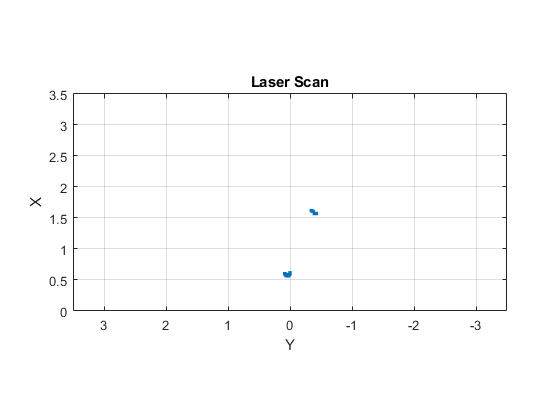

scanMsg = receive(lidarSub);
figure
rosPlot(scanMsg)

To continuously display updating lidar scans while the robot turns for a short duration, use the following while loop:

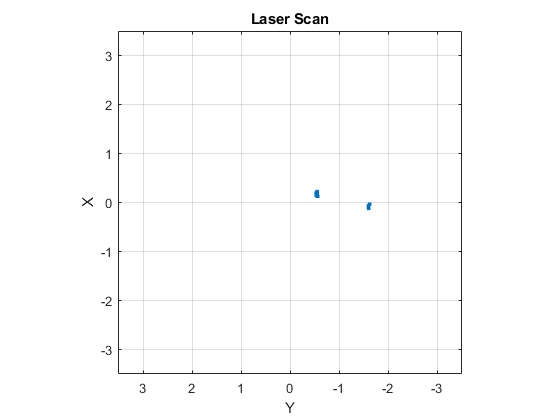

velMsg.Angular.Z = velocity;
send(robotCmd,velMsg)
tic
while toc < 20
  scanMsg = receive(lidarSub);
  rosPlot(scanMsg)
end

velMsg.Angular.Z = 0;
send(robotCmd,velMsg)

clear
rosshutdown

Shutting down global node /matlab_global_node_90274 with NodeURI http://192.168.1.5:12155/
